# Transmitter

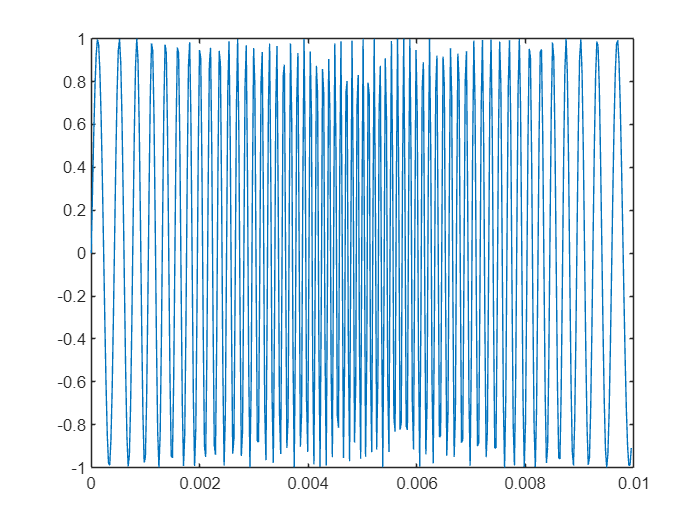

clear all;
seed = 1; % seed 1 is a magic number
rng(seed);

output_track = [];

frames = randi([0,1],100,100); % 100 frames, each 100bits

% set first 8 bits to id
for i = 1:100
    tempstr = dec2bin(i,8);
    for j = 1:8
        frames(i,j) = int32(str2double(tempstr(j)));
    end
end


t = 0:1/44100:1; % a temp time for 1 second
fc = 10*10^3; %carrier frequency 10kHz
carrier = sin(2*pi*fc*t); %about 1 sencond
crc8 = comm.CRCGenerator([1,1,0,1,0,0,1,1,1]); %x^8+x^7+x^5+x^2+x+1

% preamble 440 samples
f_p = [linspace(10*10^3-8*10^3,10*10^3,220),linspace(10*10^3,10*10^3-8*10^3,220)];
omega = 2*pi.*cumtrapz(t(1:440),f_p);
preamble = sin(omega);

figure;
plot(t(1:440),preamble);

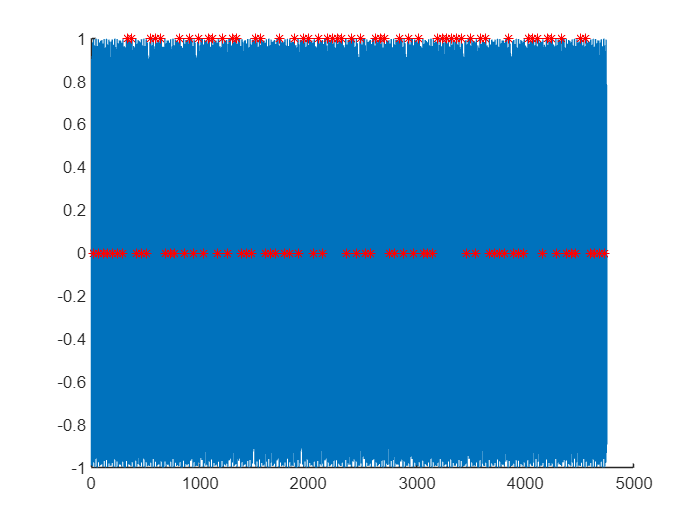



for i = 1:1
    frame = frames(i,:);
    % add crc
    frame_crc = crc8(frame')'; %108 bit
    %     frame_crc_check = generate(crc8, frame_crc(1:100)')';  % crc check
    %     if sum(frame_crc_check ~= frame_crc) ~= 0
    %        disp('error');
    %     end
    
    %modulation
    frame_wave = zeros(1,length(frame_crc)*44);
    for j = 0:length(frame_crc)-1
        frame_wave(1+j*44:44+j*44) = carrier(1+j*44:44+j*44)*(frame_crc(j+1)*2-1); % baudrate 44/44100 about 1000bps
    end
    figure;  % plot the frame
    hold on; zoom on;
    plot(frame_wave);
    plot((1:length(frame_crc))*44-22, frame_crc,'r*');
    hold off;
    
    %add preabmle
    frame_wave_pre = [preamble, frame_wave];
    
    
    %append to output_track
    output_track = [output_track,zeros(1,int32(rand()*100))]; % add some random inter frame space
    output_track = [output_track,frame_wave_pre];
    output_track = [output_track,zeros(1,int32(rand()*100))];
end


% sound(output_track,44100);

% temp = xcorr(output_track,preamble);
% plot(temp);

% figure;
% plot(output_track);

## Receiver

[soundTrack,fs] = audioread('sample_track.wav');
% output_track = soundTrack';
RxFIFO = output_track;

power = 0;
power_debug = zeros(1,length(output_track));
start_index = 0;
start_index_debug = zeros(1,length(output_track));
syncFIFO = zeros(1,440);
syncPower_debug = zeros(1,length(output_track));
syncPower_localMax = 0;


decodeFIFO = [];
decodeFIFO_Full = 1;

correctFrameNum = 0;

state = 0; % 0 sync; 1 decode

for i = 1:length(RxFIFO)
    current_sample = RxFIFO(i);
    
    power = power*(1-1/64) + current_sample^2/64;
    power_debug(i) = power;
    if state == 0
        %packet sync
        syncFIFO = [syncFIFO(2:end),current_sample];
        syncPower_debug(i) = sum(syncFIFO.*preamble)/200;
        
        if (syncPower_debug(i) > power*2) && (syncPower_debug(i) > syncPower_localMax) && (syncPower_debug(i) > 0.05)
            syncPower_localMax = syncPower_debug(i);
            start_index = i;
        elseif (i-start_index >200) && (start_index~=0)
            start_index_debug(start_index) = 1.5;
            syncPower_localMax = 0;
            syncFIFO = zeros(1, length(syncFIFO));
            state = 1;
            
            tempBuffer = RxFIFO(start_index+1:i);
            decodeFIFO = tempBuffer;
        end
    elseif state == 1
        decodeFIFO = [decodeFIFO,current_sample];
        if length(decodeFIFO) == 44*108
            % decode
            decodeFIFO_removecarrier = smooth(decodeFIFO.*carrier(1:length(decodeFIFO)),10);
            
            decodeFIFO_power_bit = zeros(1,108);
            for j= 0:108-1
                decodeFIFO_power_bit(j+1) = sum(decodeFIFO_removecarrier(10+j*44:30+j*44));
            end
            decodeFIFO_power_bit = decodeFIFO_power_bit>0;
            
            %check crc
            crc_check = generate(crc8, decodeFIFO_power_bit(1:100)')';  % crc check
            if sum(crc_check(101:end) ~= decodeFIFO_power_bit(101:end)) ~= 0
                disp('error');
            else
                tempindex = 0;
                for k = 1:8
                    tempindex = tempindex + decodeFIFO_power_bit(k)*2^(8-k);
                end
                fprintf('correct, ID: %d\n',tempindex);
                correctFrameNum = correctFrameNum+1;
            end
            start_index = 0;
            decodeFIFO = [];
            state = 0;
        else
            %
        end
    end
end

fprintf('Total Correct: %d\n',correctFrameNum);

figure;
plot(output_track);
hold on;
plot(power_debug,'r');
plot(syncPower_debug,'g');
plot(start_index_debug,'black');
hold off;